% Nathaniel Valla
% ESD II LAB 1

 
clc
clear

%% CONSTANTS
xNumPix = 752;   % total number of pixels in x direction of the sensor [px]
cx = xNumPix/2;  % centriod of camera
cxLeft = cx;     % left camera x center [px]
cxRight = cx;    % right camera x center [px]
shift = 0:cx;    % shift

%% Indepedent Variables
offset =182; % Offset of Centroid
b =60;     % baseline [mm]
f =6;    % focal length [mm] 
ps = 0.006;                         % pixel size [mm]
%% Dependent Variables 
xLeft = cxLeft*ones(size(shift)) -shift;
xRight = cxRight*ones(size(shift));
zDepth = depth(xLeft,xRight,cxLeft,cxRight, b,f,ps);

fprintf("The centriod of the object is %f meters away.",zDepth(offset));

The centriod of the object is 0.331492 meters away.

## Graphs

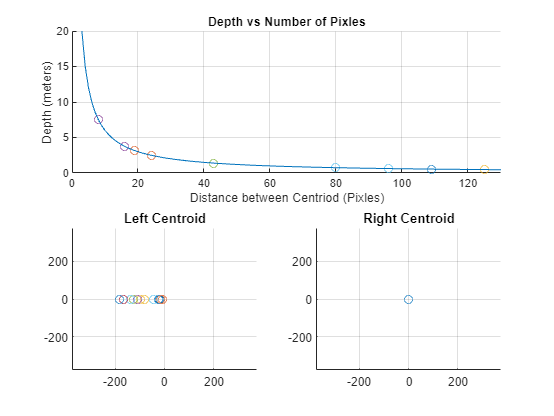

xMax = 130;
yMaxIdx = 4;

hold on
  subplot(2,2,[1,2])
  hold on
    title('Depth vs Number of Pixles')
    grid on
    plot(xRight-xLeft,zDepth);
    plot(xRight(offset)-xLeft(offset),zDepth(offset),'o');
    xlabel("Distance between Centriod (Pixles)");
    ylabel("Depth (meters)");
    xlim([0,xMax]);
    ylim([0,zDepth(yMaxIdx)]);
  hold off
  subplot(2,2,3)
  hold on
    title('Left Centroid')
    grid on
    plot(xLeft(offset)-cx,0,'o');
    xlim([min(-cx),max(cx)]);
    ylim([min(-cx),max(cx)]);
  hold off
  subplot(2,2,4)
  hold on
    title('Right Centroid')
    grid on
    plot(xRight(offset)-cx,0,'o');
    xlim([min(-cx),max(cx)]);
    ylim([min(-cx),max(cx)]);
  hold off
hold off

%% Functions

function Zm = depth(xLeft,xRight,cxLeft,cxRight, b,f,ps)
  d = (abs((xLeft-cxLeft)-(xRight-cxRight))*ps);  % disparity [mm]
  Zmm = (b * f)./d;       % depth [mm]
  Zm= Zmm./1000;          % depth [m]
end